% Sangu Meshing Code
clearvars; clc;

addpath('..')
addpath(genpath('../utilities/'))
addpath(genpath('../datasets/'))
addpath(genpath('../m_map/'))

## STEP 1: set mesh extents and set parameters for mesh.

load("G:\My Drive\Google Drive - VirginiaTech\OneDrive - Virginia Tech\03_Research\Hydrodynamic\CPBMeshFinal\Data\mat\CPP_Oceanmesh2DDomain.mat", 'model_domain')

min_el    = 100;
% mid resolution range: max_el    = [10000,-inf,-12.5; 600,-12.5,-2.5; 200,-2.5,2.5; 400,2.5,10; 5000,10,+inf]; 
max_el    = [12000,-inf,-12.5; 750,-12.5,-2.5; 200,-2.5,2.5; 400, 2.5,10; 7500,10,+inf]; 
% max_el    = 1000; 
% grade     = [0.1,-inf,-25; 0.25,-25,10; 0.5,10,+inf]; 
grade     = [0.1,-inf,-12.5; 0.05,-12.5,-2.5; 0.05,-2.5,2.5; 0.075, 2.5,10; 0.1,10,+inf]; 
% grade     = 0.5; 
R         = 3;    	

## STEP 2: specify geographical datasets and process the geographical data

## to be used later with other OceanMesh classes...

coastline = 'shorelineCPBAjusted4RiverUpdated84' %'shorelineCPBSquared84' %'Sangu_Streamline_v2'; % 'GSHHS_f_L1'; 'BD_Coast+Sangu_MainChannel';

coastline = 'shorelineCPBAjusted4RiverUpdated84'

demfile   = 'gebco_2023_n40.5_s33.5_w-78.0_e-71.0.nc';
gdat = geodata('shp',coastline,'bbox',model_domain,'dem',demfile,'h0',min_el);

Read shapefile with shaperead
Partitioning the boundary into islands, mainland, ocean
Smoothing coastline with 5 point window
Read shapefile with shaperead
Partitioning the boundary into islands, mainland, ocean
    {'Read in meshing boundary: '}    {'shorelineCPBAjusted4RiverUpdated84'}

Read in demfile gebco_2023_n40.5_s33.5_w-78.0_e-71.0.nc


## STEP 3: create an edge function class

fh = edgefx('geodata',gdat,... %% 'max_el_ns',max_el_ns,
    'fs',R,'max_el',max_el,'g',grade);

Building feature size function...
Memory management: number of loops in dpoly = 1
Elapsed time is 22.056607 seconds.
--------------------------------------------------
Releasing individual edge functions from memory...
--------------------------------------------------
Relaxing the mesh size gradient
Gradient relaxing converged!
Finalized edge function!


## STEP 4: Pass your edgefx class object along with some meshing options and

build the mesh...

mshopts = meshgen('ef',fh,'bou',gdat,'plot_on',1,'nscreen',5,'proj','trans');

Current mapping parameters -
 Projection: Transverse Mercator  (function: mp_tmerc)  
 longitudes: -77.939     -73.4994 (centered at -75.7192)
 latitudes: 35.8778      40.2077                        
 Rectangular border: off                                


Forming initial point distribution...
    for box #1
Using 0 fixed points.
Number of initial points after rejection is 407417
Elapsed time is 19.072502 seconds.
 ------------------------------------------------------->
Begin iterating...
Elapsed time is 3.776114 seconds.
Elapsed time is 2.741873 seconds.
Elapsed time is 2.691344 seconds.
Elapsed time is 2.692233 seconds.
Iteration =5
Number of nodes is 407417
Mean mesh quality is 0.85311
Min mesh quality is 0.023603
3rd sigma lower mesh quality is 0.46117
Elapsed time is 3.915252 seconds.
Elapsed time is 2.743093 seconds.
Elapsed time is 2.718575 seconds.
Elapsed time is 2.748187 seconds.
Elapsed time is 2.733102 seconds.
Iteration =10
Number of nodes is 407417
Mean mesh quality is 0.8883
Min mesh quality is 0.030372
3rd sigma lower mesh quality is 0.57053
Elapsed time is 4.028494 seconds.
Elapsed time is 2.718144 seconds.
Elapsed time is 2.745445 seconds.
Elapsed time is 2.711670 seconds.
Elapsed time is 2.729465 seconds.
Iteration =1

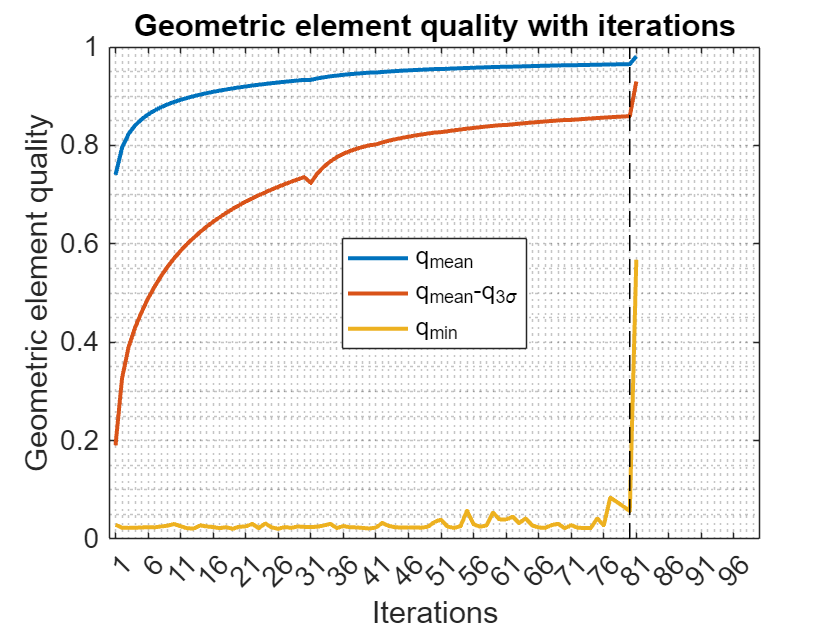

mshopts = mshopts.build;

## STEP 5: Plot it and write a triangulation fort.14 compliant file to disk.

Get out the msh class and put on nodestrings

Current mapping parameters -
 Projection: Transverse Mercator  (function: mp_tmerc)  
 longitudes: -77.495     -73.5894 (centered at -75.5422)
 latitudes: 35.9772      39.7163                        
 Rectangular border: off                                


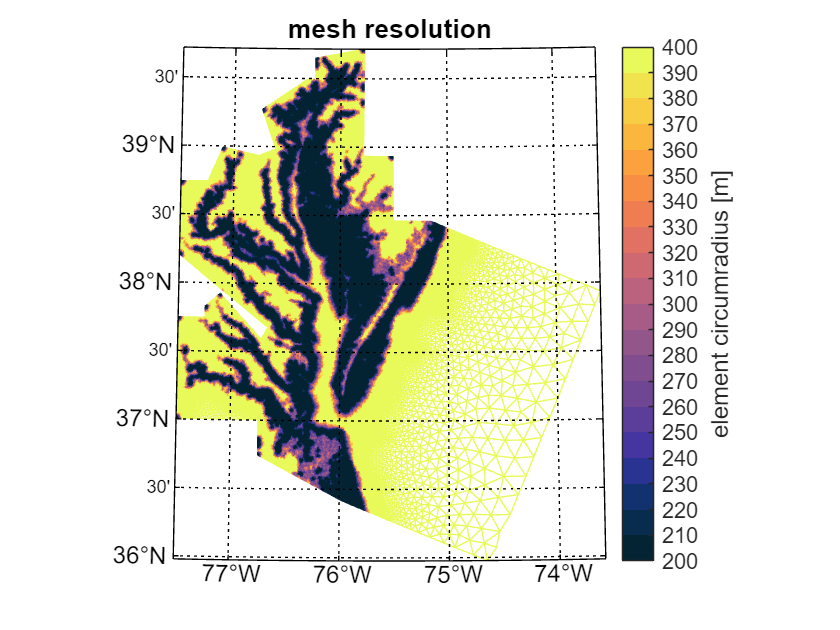

m = mshopts.grd;
% m = make_bc(m,'auto',gdat,'distance'); % make the boundary conditions
% plot(m,'type','bd');
% if you want to write into fort.14...
plot(m,'type','resomesh','colormap',[20 200 400])

 %write(m,'E:\ChesapeakeModel\Data\MeshCreation\gridsOM2D\cpb_midresRiverAdjusted_adcric');


## STEP 6: Example of plotting a subdomain with bcs

 %write(m,'E:\ChesapeakeModel\Data\MeshCreation\gridsOM2D\cpb_midresRiverAdjusted_adcric');


% m = mshopts.grd ;
% plot resolution on the mesh
% plot(m,'type','resomesh','colormap',[10 0 500])
